dhparams = [0  0	58   	0;
           0	pi/4     80   0;
          0	pi/2	135	0;
            0   -pi/4	147	0;
            0   pi/2	30   	0;
           0      0      40    0];

robot = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','fix');

setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;

addBody(robot,body1,'base')
  
%Create and add other rigid bodies to the robot. 
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','fix');
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','fix');

setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');
setFixedTransform(jnt5,dhparams(5,:),'dh');
setFixedTransform(jnt6,dhparams(6,:),'dh');

body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')

showdetails(robot)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1        fixed             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5        fixed            body4(4)   body6(6)  
   6        body6         jnt6        fixed            body5(5)   
--------------------


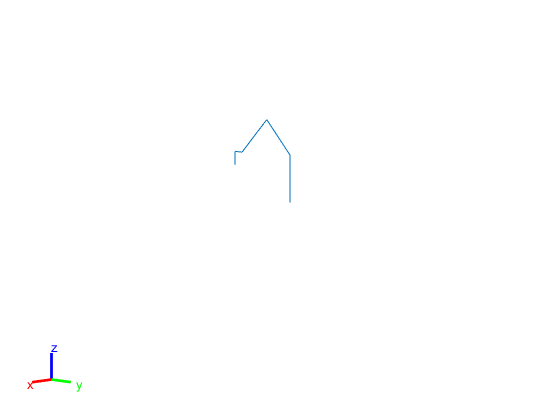

show(robot);
axis([-300,300,-300,300,-300,300])
axis off

## Manipulator Definition

The manipulator used for this example is the Rethink Sawyer™ robot manipulator. The [rigidBodyTree](docid:robotics_ref.bvan8uq-1) object that describes the manipulator is imported from a URDF (unified robot description format) file using [importrobot](docid:robotics_ref.bvlvwcs-1).

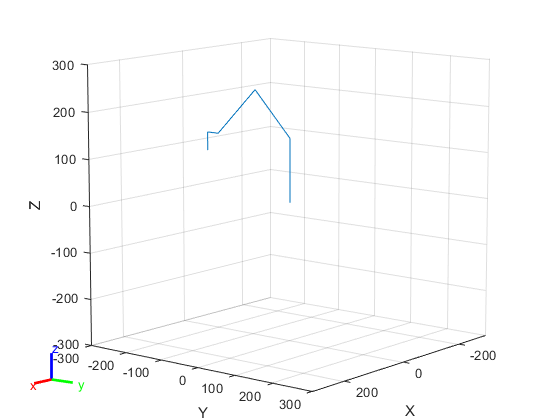

% Import the manipulator as a rigidBodyTree Object
sawyer = importrobot('sawyer.urdf');
sawyer=robot;
sawyer.DataFormat = 'column';

% Define end-effector body name
eeName = 'body6';

% Define the number of joints in the manipulator
numJoints = 3;

% Visualize the manipulator
show(sawyer);
xlim([-300.00 300.00])
ylim([-300.00 300.00]);
zlim([-300.02 300.98]);

view([128.88 10.45]);

## Waypoint Generation

In this example, the goal of the manipulator is to be able to trace out the boundaries of the coins detected in the image, `coins.png`. First, the image is processed to find the boundaries of the coins. 

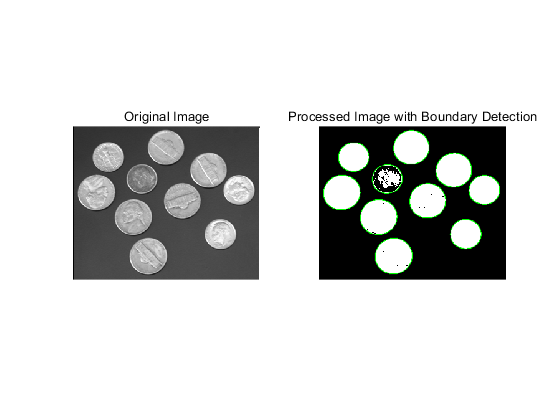

I = imread('coins.png');
bwBoundaries = imread('coinBoundaries.png');

figure
subplot(1,2,1)
imshow(I,'Border','tight')
title('Original Image')

subplot(1,2,2)
imshow(bwBoundaries,'Border','tight')
title('Processed Image with Boundary Detection')

After the image processing, the edges of the coins are extracted as pixel locations. The data is loaded in from the MAT-file, `boundaryData`. `boundaries` is a cell array where each cell contains an array describing the pixel coordinates for a single detected boundary. A more comprehensive view of how to generate this data can be found in the example, "Boundary Tracing in Images" (requires Image Processing Toolbox). 

load boundaryData.mat boundaries
whos boundaries

  Name             Size            Bytes  Class    Attributes

  boundaries      10x1             25456  cell               



To map this data to the world frame, we need to define where the image is located and the scaling between pixel coordinates and spatial coordinates.

% Image origin coordinates
imageOrigin = [0.4,0.2,0.08];

% Scale factor to convert from pixels to physical distance
scale = 0.0015;

The Euler angles for the desired end effector orientation at each point must also be defined.

eeOrientation = [0, pi, 0];

In this example the orientation is chosen such that the end effector is always perpendicular to the plane of the image. 

Once this information is defined each set of desired coordinates and Euler angles can be compiled into a waypoint. Each waypoint is represented as a six-element vector whose first three elements correspond to the desired *xyz-*positions of the manipulator in the world frame. The last three elements correspond to the ZYX Euler angles of the desired orientation.


$$\textrm{Waypoint}=\;\left\lbrack \begin{array}{cccccc}
X & Y & Z & \phi_z  & \phi_y  & \phi_x 
\end{array}\right\rbrack$$


The waypoints are concatenated to form an *n*-by-6 array, where *n* is the total number of poses in the trajectory. Each row in the array corresponds to a waypoint in the trajectory.

% Clear previous waypoints and begin building wayPoint array
clear wayPoints

% Start just above image origin
waypt0 = [imageOrigin + [0 0 .2],eeOrientation];

% Touch the origin of the image
waypt1 = [imageOrigin,eeOrientation];

% Interpolate each element for smooth motion to the origin of the image
for i = 1:6
    
    interp = linspace(waypt0(i),waypt1(i),100);
    wayPoints(:,i) = interp';
    
end


% Assemble the waypoints for boundary tracing
for i = 1:size(boundaries,1)
    
    %Select a boundary and map to physical size
    segment = boundaries{i}*scale;
    
    % Pad data for approach waypoint and lift waypoint between boundaries
    segment = [segment(1,:); segment(:,:); segment(end,:)];
    
    % Z-offset for moving between boundaries
    segment(1,3) = .02;
    segment(end,3) = .02;
    
    % Translate to origin of image
    cartesianCoord = imageOrigin + segment;
    
    % Repeat desired orientation to match the number of waypoints being added
    eulerAngles = repmat(eeOrientation,size(segment,1),1);
    
    % Append data to end of previous wayPoints 
    wayPoints = [wayPoints;
                 cartesianCoord, eulerAngles]; 
end

This array is the primary input to the model.

## Model Setup

Several parameters must be initialized before the model can be run.

% Initialize size of q0, the robot joint configuration at t=0. This will
% later be replaced by the first waypoint.
q0 = zeros(numJoints,1);

% Define a sampling rate for the simulation.
Ts = .01;

% Define a [1x6] vector of relative weights on the orientation and 
% position error for the inverse kinematics solver.
weights = ones(1,6);

% Transform the first waypoint to a Homogenous Transform Matrix for initialization
initTargetPose = eul2tform(wayPoints(1,4:6));
initTargetPose(1:3,end) = wayPoints(1,1:3)';

% Solve for q0 such that the manipulator begins at the first waypoint
ik = inverseKinematics('RigidBodyTree',sawyer);
[q0,solInfo] = ik(eeName,initTargetPose,weights,q0);

## Simulate the Manipulator Motion

To simulate the model, use the `sim` command. The model generates the output dataset, `jointData` and shows the progress in two plots:

- The **X Y Plot** shows a top-down view of the tracing motions of the manipulator. The lines between the circles occur as the manipulator transitions from one coin outline to the next.

- The **Waypoint Tracking** plot visualizes the progress in 3D. The green dot indicates the target position. The red dot indicates the actual end-effector position achieved by the end effector using feedback control.

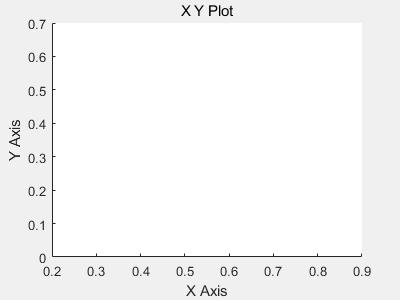

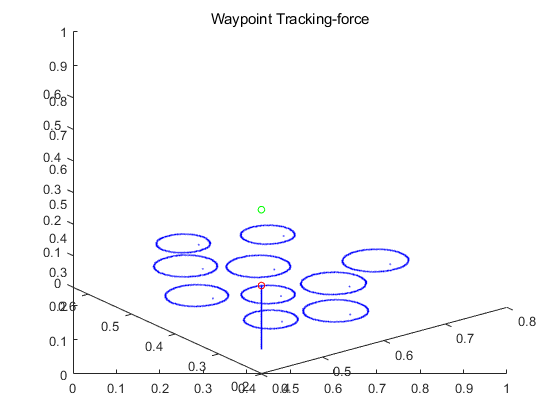

0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


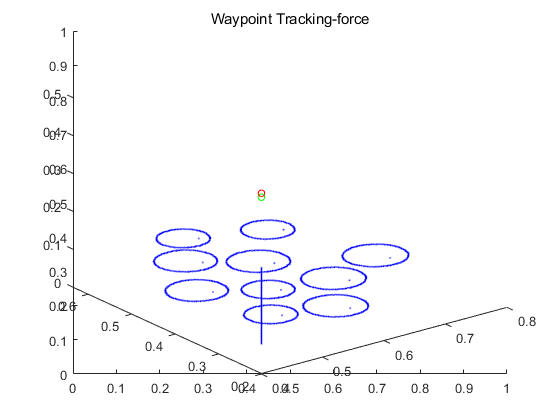

0.00 0.00 0.00 0.00 0.00 -0.00 1.00 1.00


sys =    -0.2096   -0.1336   -0.9686    0.0020    0.0013    0.0093


% Close currently open figures 
close all

% Open & simulate the model
open_system('IKTrajectoryControlExample.slx');
sim('IKTrajectoryControlExample.slx');

## Visualize the Results

The model outputs two datasets that can be used for visualization after simulation. The joint configurations are provided as `jointData`. The robot end-effector poses are output as `poseData`.

% Remove unnecessary meshes for faster visualization
%clearMeshes(sawyer);

% Data for mapping image
[m,n] = size(I);

[X,Y] = meshgrid(0:m,0:n);
X = imageOrigin(1) + X*scale;
Y = imageOrigin(2) + Y*scale;

Z = zeros(size(X));
Z = Z + imageOrigin(3);

% Close all open figures
close all

% Initialize a new figure window
figure;
set(gcf,'Visible','on');

% Plot the initial robot position
show(sawyer, jointData1(1,1:3)');

错误使用 validateDynamicsFunctionInputs
joint position vector (q) 的大小应为 3x1，但实际大小为 8x1。

出错 robotics.manip.internal.RigidBodyTree/validateConfiguration (line 1143)
                validateattributes(Q, {'double'}, ...

出错 <a href="matlab:matlab.internal.language.introspective.errorDocCallback('robotics.manip.internal.RigidBodyTree/show', 'G:\software\matlab2019b\toolbox\robotics\robotmanip\+robotics\+manip\+internal\RigidBodyTree.m', 825)" style="font-weigh

hold on

% Initialize end effector plot position
p = plot3(0,0,0,'.');
warp(X,Y,Z,I');

% Change view angle and axis
view(65,45)
axis([-.25 1 -.25 .75 0 0.75])

% Iterate through the outputs at 10-sample intervals to visualize the results
for j = 1:10:length(jointData1)
    % Display manipulator model
    show(sawyer,jointData1(j,:)', 'Frames', 'off', 'PreservePlot', false);
    
    % Get end effector position from homoegenous transform output
    pos = poseData1(1:3,4,j);
    
    % Update end effector position for plot
    p.XData = [p.XData pos(1)];
    p.YData = [p.YData pos(2)];
    p.ZData = [p.ZData pos(3)];
    
    % Update figure
    drawnow
end

*Copyright 2018 The MathWorks, Inc.*